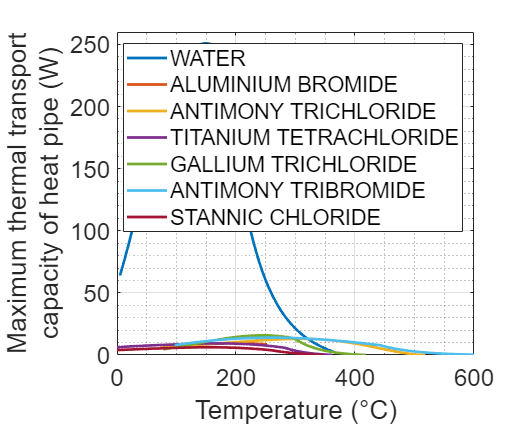

% Create figure
figure1 = figure('Name','Figure','Color',[1 1 1],'OuterPosition',[31 137 1128 914]);

Qcap_ant(Qcap_ant==100000) = 0;
Tx(Tx==0) = nan;

axes1 = axes('Parent',figure1);
hold(axes1,'on');
for x1 = 1:n
plot1 = plot(Tx(:,x1),[Qmin_ant(:,x1)],'Parent',axes1,'LineWidth',2);
set(plot1,'DisplayName',NAME(x1));
end

% Create ylabel
ylabel({'Maximum thermal transport' ;'capacity of heat pipe (W)'});

% Create xlabel
xlabel({'Temperature (°C)'});

% Uncomment the following line to preserve the X-limits of the axes
% xlim(axes1,[250 550]);
box(axes1,'on');
hold(axes1,'off');
% Set the remaining axes properties
set(axes1,'FontSize',18,'XGrid','on','XMinorGrid','on','XMinorTick','on',...
    'YGrid','on','YMinorGrid','on','YMinorTick','on')
% Create legend
legend(axes1,'show');